%Calibration data
load Calibration_data.csv

seveninch = mean(Calibration_data(:,2));
teninch = mean(Calibration_data(:,4));
twelveinch = mean(Calibration_data(:,6));
twentyfourinch = mean(Calibration_data(:,8));
thirtysixinch = mean(Calibration_data(:,10));
fourtyeightinch = mean(Calibration_data(:,12));
fiftyfourinch = mean(Calibration_data(:,14));

%Calibration testing data
load Test_Calibration_data_part_two.csv
load Calibration_data_18.csv

fourtyinch = mean(Test_Calibration_data_part_two(:,2));
eighteeninch = mean(Calibration_data_18(:,2));

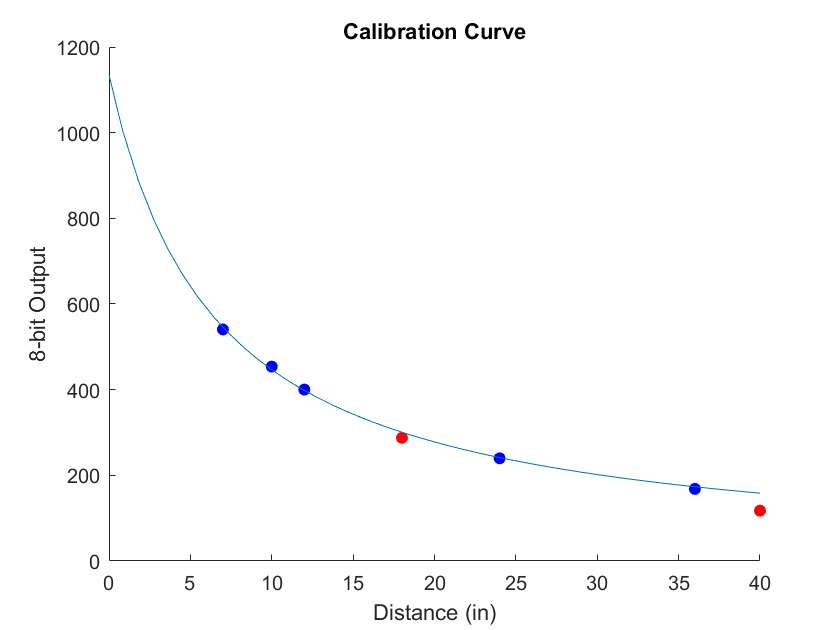

%data for finding line of best fit
bestfitx = [7,10,12,24,36];
bestfity = [seveninch, teninch, twelveinch, twentyfourinch, thirtysixinch];

%equation from line of best fit
p1 = 7362;
q1 = 6.488;

%graph of data and line of best fit
figure(1)
clf; hold on
scatter(7, seveninch, 'b', 'filled')
scatter(10, teninch, 'b', 'filled')
scatter(12, twelveinch, 'b', 'filled')
scatter(24, twentyfourinch, 'b', 'filled')
scatter(36, thirtysixinch, 'b', 'filled')
scatter(40, fourtyinch, 'r', 'filled')
scatter(18, eighteeninch, 'r', 'filled')
fplot(@(x) (p1)./(x+q1))
xlabel("Distance (in)")
xlim([0 40])
ylabel("8-bit Output")
title("Calibration Curve")


% these two were measured for calibration, but have been excluded because
% they appear to be outside the sensor's accurate range
% scatter(48, fourtyeightinch)
% scatter(54, fiftyfourinch)
